Найти целочисленное решение дифуров на отрезке [0, 5] с 100 отсчётами, вывести графики поотдельности в одном окне и и два графика совместно в одном окне

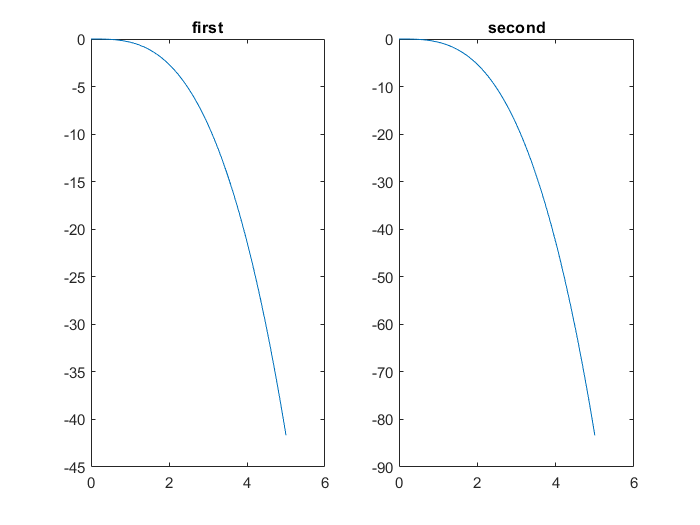

t = linspace(0, 5, 200);
y1 = @(t, y) -t*t;
y2 = @(t, y) -2*t*t;

[t, y1] = ode45(y1, t, 0);
figure(1);
subplot(1,2,1);
plot(t, y1);
title("first");

[t, y2] = ode45(y2, t, 0);
subplot(1,2,2);
plot(t, y2);
title("second");

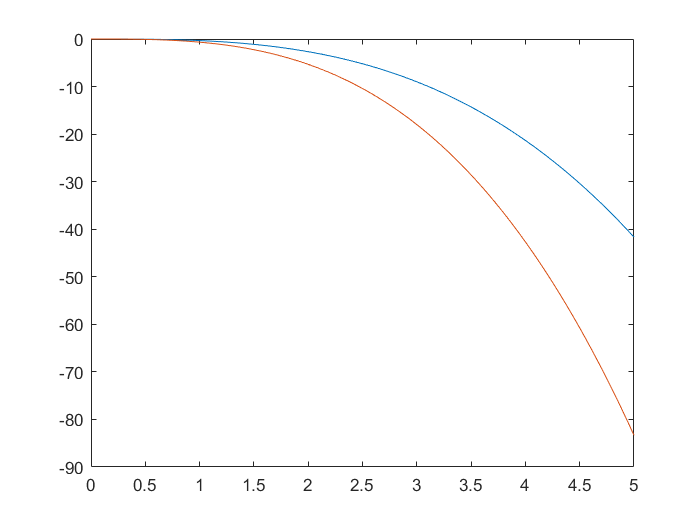



figure(4);
plot(t, y1);
hold on
plot(t, y2);
hold off;

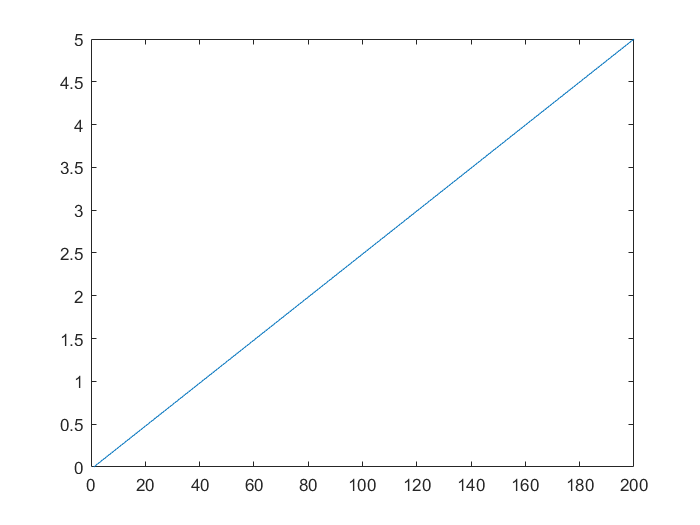

plot(t)

сгенерить случайную матрицу, посчитать определитель, найти с.ч. и с.в. , сгенерировать случ. вектор, решить СЛУ из Ма и в-ра, если определитель не нулевой, вывести решения на графике

n = 3;
A = rand(n);
detd = det(A);
[v, lam] = eig(A);
A*v == v*lam

ans = 3×3 logical array
   0   0   0
   0   0   0
   0   0   0


b = rand(n, 1);
x = A\b

x =    -1.7666
   -2.1218
    2.9108


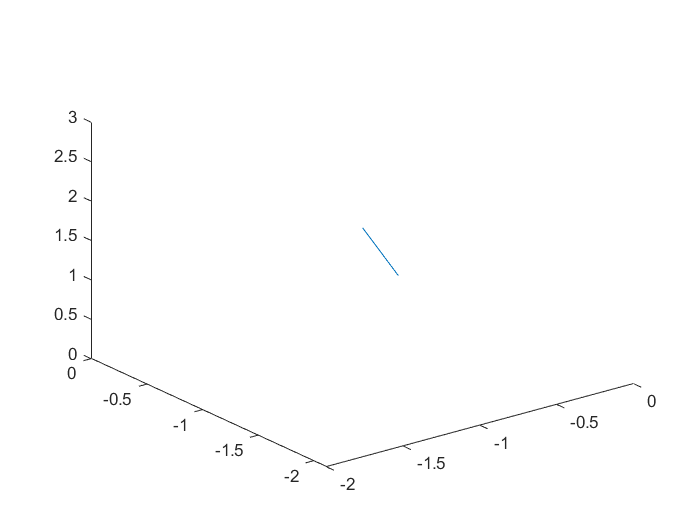

plot3([0, x(1)], [0, x(2)], [0, x(3)])

Нарисовать синус + зашумлённый

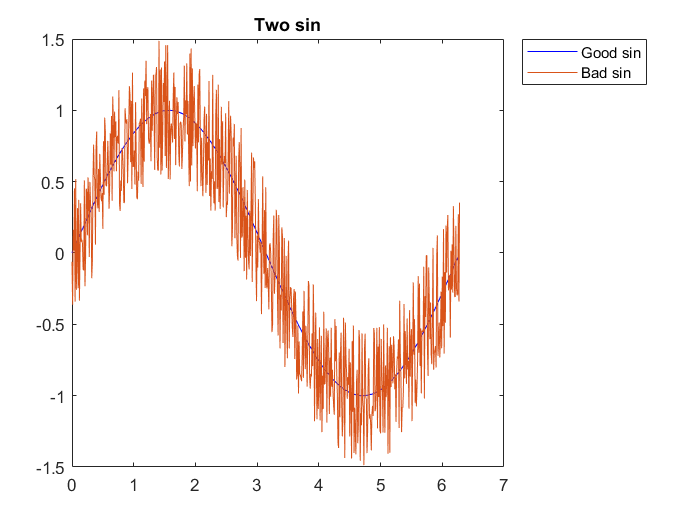

x = 0:0.01:2*pi;
y = sin(x);
plot(x, y, 'b', x, y + rand(1, length(x)) - 0.5)
legend("Good sin", "Bad sin")
title("Two sin")

LTI по передаточной функции H(s) = (2s + 4)(s^2 + 2s + 1)

num = [2, 4];
den = [1, 2, 1];
t = linspace(0, 5, 100)

t =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


tf_sys = tf(num, den)

tf_sys =
 
     2 s + 4
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



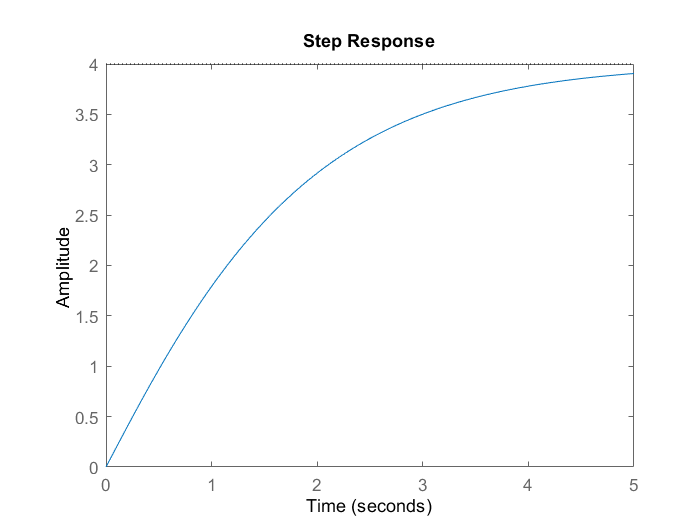

step(tf_sys, t)

y = sin(2*pi*t)

y =          0    0.3120    0.5929    0.8146    0.9549    0.9999    0.9450    0.7958    0.5671    0.2817   -0.0317   -0.3420   -0.6182   -0.8326   -0.9638   -0.9989   -0.9341   -0.7761   -0.5406   -0.2511    0.0634    0.3717    0.6428    0.8497    0.9718    0.9969    0.9224    0.7557    0.5137    0.2203   -0.0951   -0.4009   -0.6668   -0.8660   -0.9788   -0.9938   -0.9096   -0.7346   -0.4862   -0.1893    0.1266    0.4298    0.6901    0.8815    0.9848    0.9898    0.8960    0.7127    0.4582    0.1580


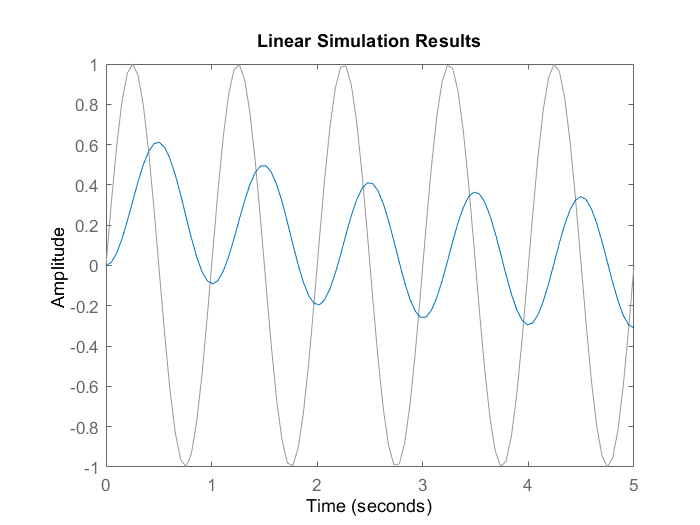

lsim(tf_sys, y, t)

Сгенерировать y = sin(2pi*t) на [-2, 2] с шагом 0.05 четным отсчётам присвоить 1 . Найти производную на отрезке. Вывести на одном графике

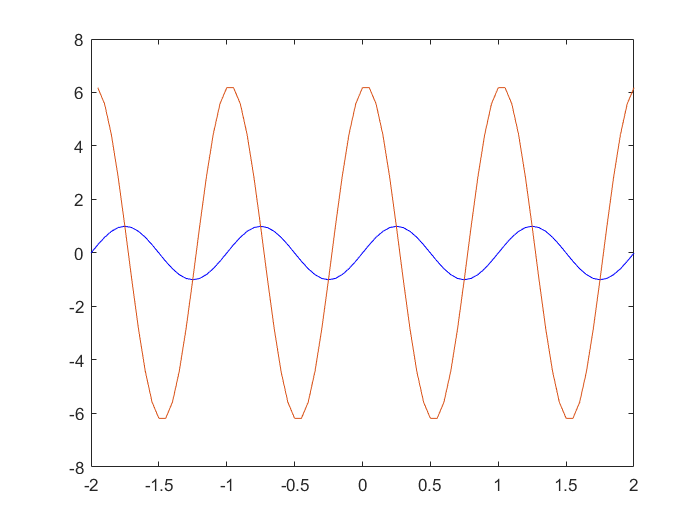

t = -2:0.05:2;
y = sin(2*pi*t);
y1 = y;
y1(2:2:end) = 1;
plot(t, y, 'b')
hold on

y_diff = diff(y)./diff(t);
plot(t(2:end), y_diff)
hold off;

Сгеерировать сигнал y = t^2 - 3t + 2 + r(t) на 0,3 с 100 отсчётами, отрицательным значениям присвоить 0. Найти производную. Вывести на одном графике.

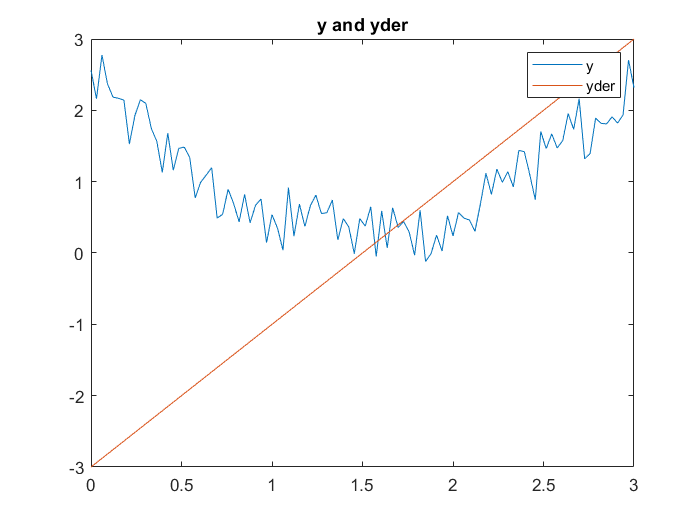

t = linspace(0, 3, 100);
p = [1, -3, 2];
y = polyval(p, t) + rand(size(t));
y1 = y;
y1(y1 < 0) = 0;
p_der = polyder(p);
y_der = polyval(p_der, t);
plot(t, y, t, y_der);
legend("y", "yder");
title("y and yder");

Найти Co 

A = [1  1;
     4 -2];
B = [1 -1;
     1 -1];
my_co = [B A*B]

my_co =      1    -1     2    -2
     1    -1     2    -2


Co = ctrb(A,B)

Co =      1    -1     2    -2
     1    -1     2    -2


Найти значения полинома с корнями 1 2 3 4 на отрезке 0 5 с шагом 0.1. У отриц поменять знак Найти производную. Вывести на графике.

r = [1 2 3 4];
p = poly(r)

p =      1   -10    35   -50    24


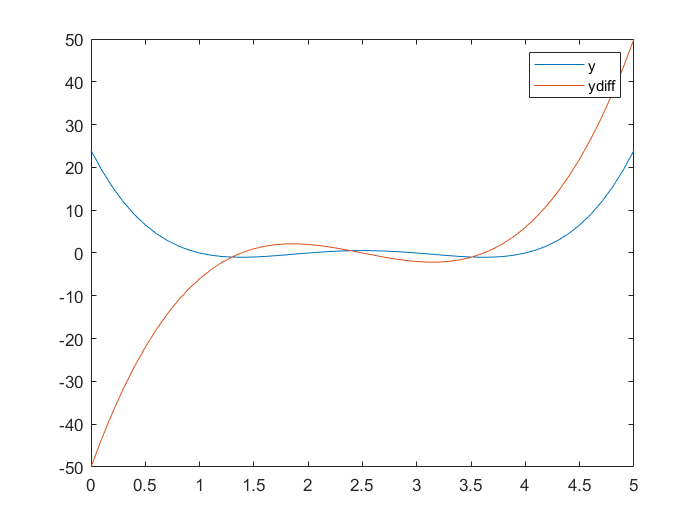

x = 0:0.1:5;
y = polyval(p, x);
y1 = abs(y);
p_der = polyder(p);
y_der = polyval(p_der, x);
plot(x, y, x, y_der)
legend("y", "ydiff")